# Synchronization Algorithms implementation

### Introduction

From previous script, we have seen and implemented the main issues of synchronization. The aim of this script is to correct those errors. To do so, 2 main algorithms are needed : the gardner algorithm to track the correct time instant to sample and the DA frame acquisition to remove CFO and phase shift. 

The first algorithm to be implemented is the NDA (Non Data Aided) Gardner algorithm because this algorithm is resistant to both CFO and phase shift. CFO and phase shift will be corrected by the DA frame acquisition.  

clc; close all; clearvars;
addpath("C:\Users\François\Downloads\MA1\MC\project\ELEC-H-401-DVB-S2\1 Optimal communication chain over the ideal channel");

For the **DA frame acquistion**, known pilots will be sended before the data packets to estimate the ToA (Time of arrival) and the CFO. The choice of the pilot length must be high enough to correctly acquire the frame but not to long so that the data rate can be kept high.  

%% parameters
Nbit = 1800;

Nbps = 2;    %Nombre of bits per symbol (1 = BPSK, 2 = 4QAM, 4 = 16QAM, 6 = 64QAM)
pilot_symbol_length = 24;
pilot_length = pilot_symbol_length*Nbps ; %20 in the course but here at 24 so it can be easily mapped.
pilot = randi(2,1,pilot_length)-1;
pilot_ratio = 0.1;
data_length = pilot_length/pilot_ratio -pilot_length; % 90% of a codeblock is the data
data_symbol_length = data_length/Nbps;
codeblock_length = data_length+pilot_length;

f_cut = 1e6; %Hz Cutoff frequency
fsymb = 2*f_cut;
T_symb = 1/fsymb;
M = 16; %Upsampling factor (au moins plus grand que 4) multiple de fsamp
fsamp = fsymb*8; % Sampling frequency (rule of thumb for the 10 25 times f_cut) Its the freq on which the conv of the filter and the signal will be done --> has to be the same !!!
EbNo = 6; %Energy of one by over the PSD of the noise ratio (in dB)
N_taps = 101; %number of taps of the filter
beta = 0.3; %Makes the window smoother as beta increases // roll-off factor given in the specifications

%% Bit Generator

bits = randi(2,1,Nbit)-1;
bits_save = bits;
bits_and_pilots = [];
pilot_offset = 13*Nbps;
%pilot_offset = randi(data_length/2,1,1);
pilot_offsetbits = randi(2,1,pilot_offset)-1;
bits_and_pilots = [bits_and_pilots pilot_offsetbits];

for i = 1:data_length:Nbit-data_length
    bits_and_pilots = [bits_and_pilots pilot bits(i:i+data_length-1)]; 
end
bits = bits_and_pilots;

check_mult = mod(Nbit,Nbps);
if check_mult == 0
    bit_tx = bits;
else
    bit_tx = [bits  zeros(1,Nbps - check_mult)];
end
Nbit_tx = length(bit_tx);

%% Mapping
%Maps the bits into desired symbols in the complex plane 
if (Nbps > 1)
    symb_tx = mapping(bit_tx', Nbps, 'qam')';
    pilot_mapped = mapping(pilot',Nbps,'qam')';
else
    symb_tx = mapping(bit_tx', Nbps, 'pam')';
    pilot_mapped = mapping(pilot', Nbps, 'pam')';
end

%figure(12); grid on; title("Mapped signal in absolute value"); stem(abs(symb_tx));
%% Upsampling

upsampled_symb_tx = UpSampling(symb_tx,Nbit_tx,Nbps,M);


%% Transmitter Filter

filter = HalfrootNyquistFilter(fsamp,T_symb,N_taps); %So we compute de filter only 1 time as this is the same

signal_tx = conv(upsampled_symb_tx,filter);%Convolution of the signal with the filter
signal_tx1 = conv(upsampled_symb_tx(1:M),filter);


%figure(7); stem(abs(signal_tx)); title("transmited signal")
%signal_tx = upsampled_symb_tx;


%% Transmission Channel

%signal_rx = NoiseAddition(signal_tx,EbNo,fsamp,Nbit);      %With Noise
signal_rx = signal_tx;                              %Without Nosie

% signal_rx1 = NoiseAddition(signal_tx1,EbNo,fsamp,Nbps);      %With Noise
signal_rx1 = signal_tx1;      %With Noise

%fig_signal_tx = figure('Name','signal_tx','NumberTitle','off');plot(signal_rx,'b.');grid on;hold on;plot(signal_tx,'ro');


%% CFO and phase shift addition
fs_passband= 2e9; %Hz
CFO = 2; % CFO in ppm (2 to see something)
CFO = fs_passband*CFO*1e-6; %CFO in Hz
[signal_rx_CFO, phase_shift, time_shift] = Add_sync_errors(signal_rx,CFO,fsamp,M,Nbps);
%figure;subplot(1,2,1); scatter(real(signal_rx_CFO),imag(signal_rx_CFO)); axis equal; title("CFO and phase shift effects"); legend("CFO and phase shift"); subplot(1,2,2); scatter(real(signal_rx),imag(signal_rx)); axis equal; legend( "No CFO and phase shift")

%% Matched filter 
matched_filter = flip(filter); %Get the time reversal of the filter g(-t) 
upsampled_signal_rx = conv(signal_rx_CFO,matched_filter,'valid');
vanilla_upsampled_signal = conv(signal_rx,matched_filter,'valid');

### The Gardner Algorithm

*Code is in the GardnerDownsampler function*

The feedback loop implementation of the Gardner algorithm follows this recursive equation : 

## 
$$\hat{\epsilon}[n+1] = \hat{\epsilon}[n]+2 \kappa \Re\left[y_{\hat{\epsilon}[n]}[n-1 / 2]\left(y_{\hat{\epsilon}[n]}^{*}[n]-y_{\hat{\epsilon}[n-1]}^{*}[n-1]\right)\right]

(1)$$


##  Where $y_{\epsilon}[n] := \int^{\infty}_{-\infty}{r(t)g^{*}(t-nT -\epsilon T)} (2)$ 

In this code, $y_\epsilon [n]
$ is `signal_rx `and $\epsilon$ is the `time_shift `given in indices. 

(1) is interpreted has the estimation of the correct sample time shift. Once this time shift maximizes the signal energy, it is assumed to be the correct time shift.

We have to add the time shift in the matched filter to get (2) We therefore have to get rid of it after the matched filter.

The following graph shows how the algorithm works. 

## 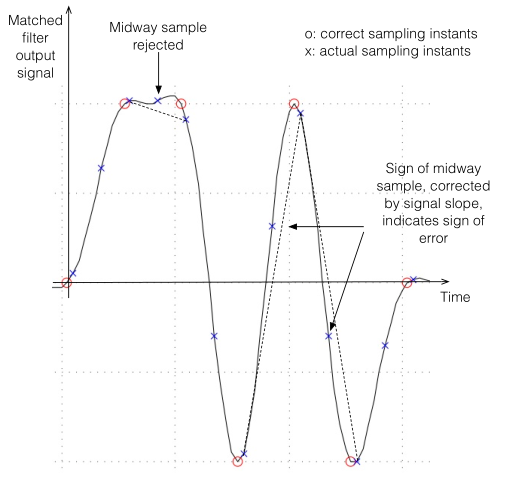

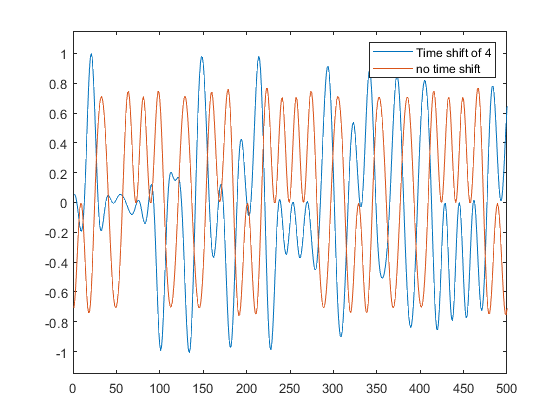

kappa = 0.02; %correction slope coefficient trade off time/noise reduction
figure; plot(real(upsampled_signal_rx)); hold on; plot(real(vanilla_upsampled_signal));
legend("Time shift of "+string(time_shift)  ,"no time shift");
xlim([0 500])
ylim([-1.15 1.15])

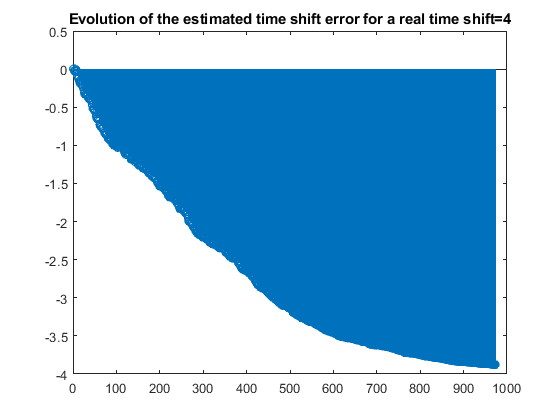


%upsampled_gardned_signal_rx = signal_rx_CFO;


[y,eps_hat] = Gardner(upsampled_signal_rx,M,kappa);
figure; stem(eps_hat);title("Evolution of the estimated time shift error for a real time shift="+string(time_shift));

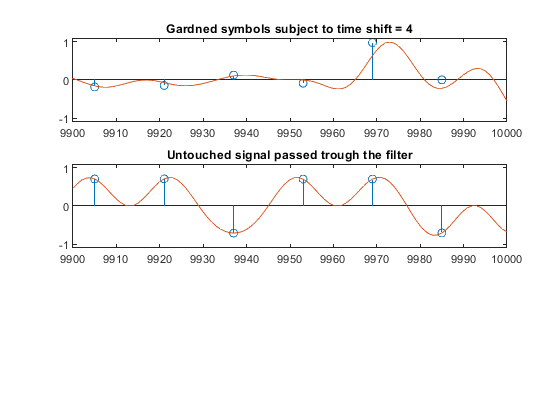


%% Downsampling
%symb_rx = DownSampling(upsampled_gardned_signal_rx,Nbit_tx,Nbps,M);
symb_rx_vanilla = DownSampling(vanilla_upsampled_signal,Nbit_tx,Nbps,M);
figure; subplot(3,1,1); stem(1:M:Nbit_tx*M/Nbps,real(y));hold on; plot(real(upsampled_signal_rx)); title("Gardned symbols subject to time shift = "+string(time_shift));
subplot(3,1,2);stem(1:M:Nbit_tx*M/Nbps,real(symb_rx_vanilla));hold on; plot(real(vanilla_upsampled_signal)); title("Untouched signal passed trough the filter");

subplot(3,1,1)
xlim([9900 10000])
ylim([-1.10 1.10])
subplot(3,1,2)
xlim([9900 10000])
ylim([-1.10 1.10])

## Da Frame acquistion

Has to be done after the Gardner algorithm to correct CFO and ToA problems. 

%% DA frame acquistion
K = 4;
[symb_rx,n_hat,df_hat] = Da_frame_acq(y,pilot_mapped,data_symbol_length,K,T_symb,Nbps,Nbit)

symb_rx =   -0.2892 - 0.4660i   0.6085 - 0.3358i  -0.5924 - 0.3699i  -0.5448 + 0.5840i  -0.4461 + 0.2446i  -0.1689 - 0.7174i   0.6318 - 0.2044i  -0.6626 + 0.4269i   0.6567 - 0.3784i  -0.7711 + 0.3235i  -0.2643 - 0.6602i  -0.5683 + 0.3593i  -0.0556 - 0.7218i   0.6971 - 0.1946i  -0.4502 - 0.5584i  -0.5767 + 0.3640i   0.7630 - 0.2328i  -0.8311 + 0.1585i  -0.0355 - 0.6541i   0.2372 + 0.9153i   0.0466 + 0.5991i  -0.7433 + 0.0227i   0.1973 + 0.6747i  -0.6471 - 0.0680i   0.7894 - 0.0954i  -0.8579 + 0.1434i   0.1623 + 0.6516i   0.0798 - 0.8948i   0.8101 + 0.1375i   0.5812 + 0.1077i  -0.2046 + 0.6636i   0.0438 - 0.8245i  -0.0774 + 0.7904i   0.0386 - 0.8715i  -0.6833 + 0.0320i   0.8637 + 0.2500i  -0.1913 + 0.7169i   0.8080 + 0.0330i   0.5675 + 0.2107i  -0.3898 + 0.7495i  -0.1625 + 0.5089i   0.3612 - 0.8460i   0.5979 + 0.3541i  -0.8180 - 0.3775i   0.4372 - 0.7136i   0.2485 - 0.4912i  -0.3625 + 0.7684i   0.4721 - 0.7530i   0.5759 + 0.5322i  -0.5901 + 0.5656i


n_hat =     13   253   493   733


df_hat = 	1.0e+06 *

   -1.0047   -1.0047   -1.0047   -1.0047


%% Demapping
 
if (Nbps > 1)
    bit_rx = demapping(symb_rx', Nbps, 'qam')';
else
    bit_rx = demapping(real(symb_rx)', Nbps, 'pam')';
end

bit_down_scaled = bit_rx(1:Nbit);

%% Bits check

ErrorRatio = ErrorCalculator(bit_rx,bits_save)

ErrorRatio = 0.5222

%figure; plot(symb_tx-symb_rx);title("error between symb_rx and symb_tx");

blublub